**Análisis frecuencial**

Para continuar se realizará el análisis frecuencial de señales simuladas que representan la captura realizada del sensor inercial (IMU) cuando este está en movimiento.

Como en el caso anterior (estático) se inicia con cargar los datos.

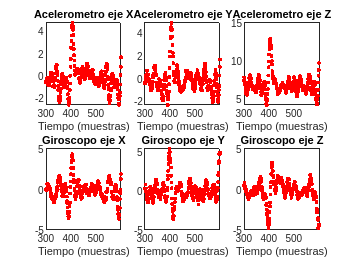

M = readmatrix('motion.csv');
Ac_x = M(:,1);
Ac_y = M(:,2);
Ac_z = M(:,3);
 
Gy_x = M(:,4);
Gy_y = M(:,5);
Gy_z = M(:,6);

n = 0:length(Ac_x)-1;
figure()
subplot(2,3,1)
plot(n(300:599),Ac_x(300:599),'r.')
title('Acelerometro eje X')
xlabel('Tiempo (muestras)')
subplot(2,3,2)
plot(n(300:599),Ac_y(300:599),'r.')
title('Acelerometro eje Y')
xlabel('Tiempo (muestras)')
subplot(2,3,3)
plot(n(300:599),Ac_z(300:599),'r.')
title('Acelerometro eje Z')
xlabel('Tiempo (muestras)')

subplot(2,3,4)
plot(n(300:599),Gy_x(300:599),'r.')
title('Giroscopo eje X')
xlabel('Tiempo (muestras)')
subplot(2,3,5)
plot(n(300:599),Gy_y(300:599),'r.')
title('Giroscopo eje Y')
xlabel('Tiempo (muestras)')
subplot(2,3,6)
plot(n(300:599),Gy_z(300:599),'r.')
title('Giroscopo eje Z')
xlabel('Tiempo (muestras)')

A partir de los gráficos se observa que las señales presentan un cierto comportamiento rítmico, pero no es posible determinar que tanto afecta el ruido a estas señales.

Para comprender la información del sensor, resulta útil observar el espectro de frecuencia. Se procede de la misma forma que antes calculado la FFT y obteniendo la magnitud del espectro.

FAc_x = abs(fft(Ac_x));
FAc_y = abs(fft(Ac_y));
FAc_z = abs(fft(Ac_z));

FGy_x = abs(fft(Gy_x));
FGy_y = abs(fft(Gy_y));
FGy_z = abs(fft(Gy_z));

Luego se procede a obtener las gráficas correspondientes.

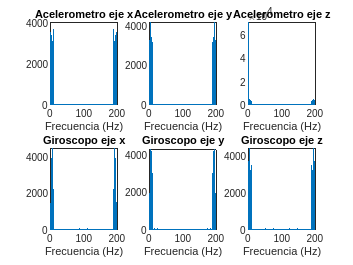

fr = n*200/length(FAc_x);
figure()
subplot(2,3,1)
plot(fr,FAc_x)
title('Acelerometro eje x')
xlabel('Frecuencia (Hz)')
subplot(2,3,2)
plot(fr,FAc_y)
title('Acelerometro eje y')
xlabel('Frecuencia (Hz)')
subplot(2,3,3)
plot(fr,FAc_z)
title('Acelerometro eje z')
xlabel('Frecuencia (Hz)')

subplot(2,3,4)
plot(fr,FGy_x)
title('Giroscopo eje x')
xlabel('Frecuencia (Hz)')
subplot(2,3,5)
plot(fr,FGy_y)
title('Giroscopo eje y')
xlabel('Frecuencia (Hz)')
subplot(2,3,6)
plot(fr,FGy_z)
title('Giroscopo eje z')
xlabel('Frecuencia (Hz)')

A partir de la observación de los gráficos se observa que las amplitudes son de un orden mucho mayor que las mismas gráficas obtenidas con el sensor quieto.

Lo anterior sugiere que las información relacionada con el movimiento tiene una proporción mucho mayor al ruido presente. Para ello se le sugiere hacer zoom en diferentes partes de los gráficos. es importante observar los valores de altura los componentes más grandes del espectro de frecuencia. Recuerde que para conocer la amplitud del armónico de interes, se debe dividir el valor de la altura de la muestra entre el número total de muestras.

Es de anotar que la información relacionada con el movimiento se encuentra dentro de un cierto ancho de banda que es facilmente visible. Para este caso, el mencionado ancho de banda está entre 0 y 10 Hz.

El gráfico del acelerómetro en el eje Z presenta un comportamiento diferente por el efecto de la gravedad,  el cual se ve en la frecuencia 0 Hz.